## Stillbilder

clear
image = double(imread('baboon.png'));
%image = double(imread('boat.png'));
%image = double(imread('woodgrain.png'));

[x,y] = size(image);

insignal = reshape(image,1,x*y)' % vert

insignal =    150
   125
    74
    79
    84
    84
    38
    23
    54
    32


%insignal = reshape(image',x*y,1); % hor

theMax = max(max(minshift(insignal)))

theMax = 237

insignal = uint8(minshift(insignal));

% ny
pair_symbol_count = zeros(theMax);

for i = 1:size(insignal, 1)-1
    index = insignal(i);
    index2 = insignal(i + 1);
    pair_symbol_count(index, index2) = pair_symbol_count(index, index2)+1;
end

p_pairs = pair_symbol_count/(size(insignal, 1) - 1);

p_pairs = p_pairs(find(p_pairs));

Hxx = entropyOfDistribution(p_pairs) / 2

Hxx = 7.0155





p = distribution2d(image)

p =     0.0002
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001


H1 = entropyOfDistribution(p)

H1 = 7.4745

#### Parentropi horisontellt


$$H\left(X_{i,j} ,X_{i+1,j} \right)$$



data = reshape(image,1,x*y);

horizontal_data = zeros(size(data));

horizontal_data(1,1) = data(1,1);
% Skiftar
for i = 2:size(data,2)
%     data(1,i)-data(1,i-1)
    horizontal_data(1,i) = data(1,i) - data(1,i-1);
end

horizontal_data

horizontal_data =    150   -25   -51     5     5     0   -46   -15    31   -22    -5     1     4   -13    -3    54    13   -30     5    58    39   -74   -38     7    36    34   -18    33   -20   -78    48   -38    15    18     2   -21     9   -22    -2    50   -37   -19    11    22     8    10   -27    68   -77   -10


min(horizontal_data)

ans = -198


% Tar bort negativa värden
horizontal_data = minshift(horizontal_data);

p2 = distribution(horizontal_data')

p2 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


H_hori = entropyOfDistribution(p2)

H_hori = 6.8975

#### Parentropi vertikalt


$$H\left(X_{i,j} ,X_{i,j+1} \right)$$


% Transponera bilden ger vertikala grannar
data = reshape(image',1,x*y);
vertical_data = zeros(size(data));

vertical_data(1,1) = data(1,1);
% Skiftar
for i = 2:size(data,2)
    vertical_data(1,i) = data(1,i) - data(1,i-1);
end
% Tar bort negativa värden
vertical_data = minshift(vertical_data);

p3 = distribution(vertical_data');
H_vert = entropyOfDistribution(p3)

H_vert = 6.5521

#### Betingad


$$\left.H\left(X_{i+1,j} \right|X_{i,j} \right)$$


H_hori_cond = H_hori - H1

H_hori_cond = -0.5769

H_hori_cond = H_hori - Hxx

H_hori_cond = -0.1180

H1 - Hxx

ans = 0.4590

 H(Xi,j+1 | Xi,j) 

H_vert_cond = H_vert - H1

H_vert_cond = -0.9223

#### Huffmankodning


$$Y_{i,j} =X_{i,j} -P_{i,j}$$



l2 = huffman(p2)

l2 = 6.9323

l3 = huffman(p3)

l3 = 6.5818


data = padarray(image,[1 1],128, 'both');

pe1 = image;
%Horizontal
for x = 2:size(image,1) 
    for y = 2:size(image,2) 
        %newimage(x,y) = data(x,y) - (data(x-1,y) + data(x,y-1) - data(x-1,y-1));
        pe1(x,y) = pe1(x,y) - data(x-1,y);
    end
end

%Vertical
pe2 = image;
for x = 2:size(image,1) 
    for y = 2:size(image,2) 
        %newimage(x,y) = data(x,y) - (data(x-1,y) + data(x,y-1) - data(x-1,y-1));
        pe2(x,y) = pe2(x,y) - data(x,y-1);
    end
end

%Conditional
pe3 = image;
for x = 2:size(image,1) 
    for y = 2:size(image,2) 
        %newimage(x,y) = data(x,y) - (data(x-1,y) + data(x,y-1) - data(x-1,y-1));
        pe3(x,y) = pe3(x,y) - (data(x-1,y) + data(x,y-1) - data(x-1,y-1));
    end
end

l = huffman(p)

l = 7.5171

H1 = entropyOfDistribution(p)

H1 = 7.4745


%prediction_error = prediction_error(2:end-1,2:end-1);
%prediction_error = minshift(prediction_error);
[row,col] = size(pe1);
data_l4_h = reshape(pe1,row*col,1);
data_l4_h = minshift(data_l4_h);
p4_h = distribution(data_l4_h);
l4_h = huffman(p4_h)

l4_h = 7.2685

H_hori = entropyOfDistribution(p4_h)

H_hori = 7.2411


[row,col] = size(pe2);
data_l4_v = reshape(pe2,row*col,1);
data_l4_v = minshift(data_l4_v);
p4_v = distribution(data_l4_v);
l4_v = huffman(p4_v)

l4_v = 7.2355

H_vert = entropyOfDistribution(p4_v)

H_vert = 7.2104


[row,col] = size(pe3);
data_l4_c = reshape(pe3,row*col,1);
data_l4_c = minshift(data_l4_c);
p4_c = distribution(data_l4_c);
l4_c = huffman(p4_c)

l4_c = 7.3819

H_cond = entropyOfDistribution(p4_c)

H_cond = 7.3582

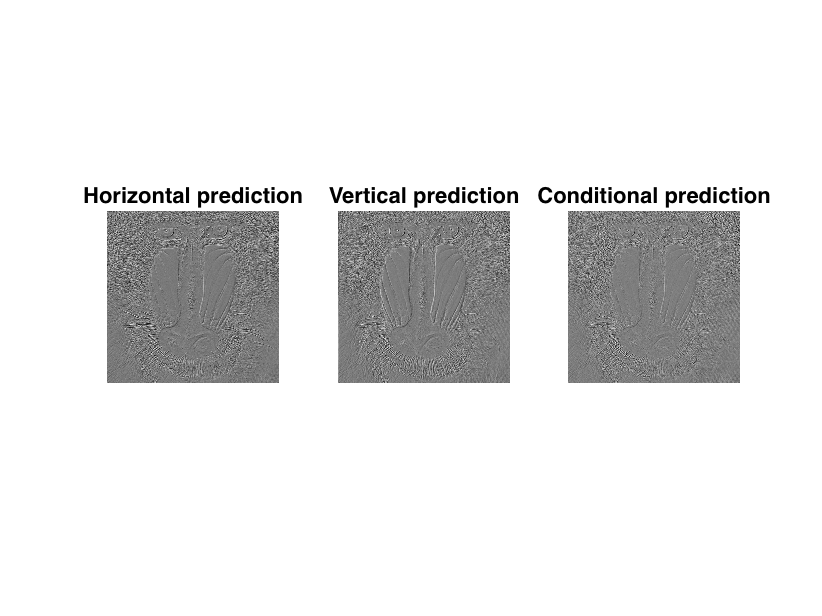



figure;
subplot(1,3,1);
imshow(minshift(pe1) / max(max(minshift(pe1))))
txt1 = ['Bitrate: ' num2str(l4_h)];
title('Horizontal prediction');
subtitle(txt1)

subplot(1,3,2);
imshow(minshift(pe2) / max(max(minshift(pe2))))
title('Vertical prediction');
txt2 = ['Bitrate: ' num2str(l4_v)];
subtitle(txt2)

subplot(1,3,3);
imshow(minshift(pe3) / max(max(minshift(pe3))))
title('Conditional prediction');
txt3 = ['Bitrate: ' num2str(l4_c)];
subtitle(txt3)